# Fitting Data with Outliers

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

data = readtable("data\dataPoly.xlsx", Sheet="data");
dataTrain = readtable("data\dataPoly.xlsx", Sheet="dataTrain");
dataTest = readtable("data\dataPoly.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           200x2              4387  table              
  dataTest        60x2              2147  table              
  dataTrain      140x2              3427  table              



## Task 1

The table `data` has been split into training and test sets: `dataTrain` and `dataTest`. The response variable is `"y"`.

Fit a model and evaluate at test values.

mdl = fitrgp(dataTrain, "y");
[yPred, ~, yInt] = predict(mdl, dataTest);

Plot the results.

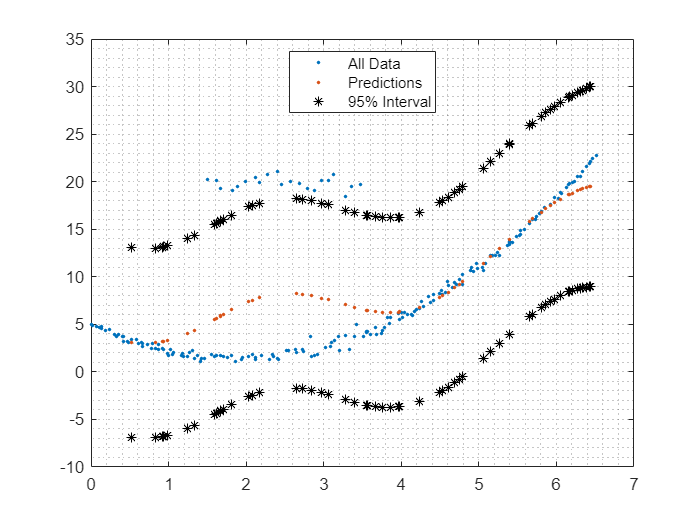

plot(data.x, data.y, ".")
hold on
plot(dataTest.x, yPred, ".")
plot(dataTest.x, yInt, "k*")
grid minor
hold off
legend("All Data", "Predictions", "95% Interval", "Location", "Best")